ЛАБОРАТОРНА РОБОТА №4

з навчальної дисципліни «Математичне моделювання систем і процесів»

Виконав:

Студент 5 курсу

Групи ФФ-21мн

Бондар О.В.

Перевірив:

Гордійко Н.О.

Варіант №1 

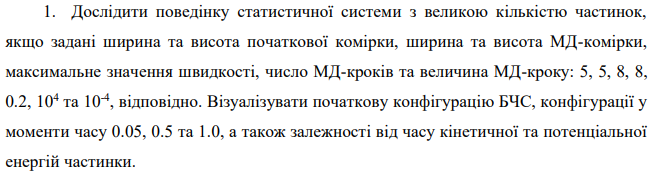

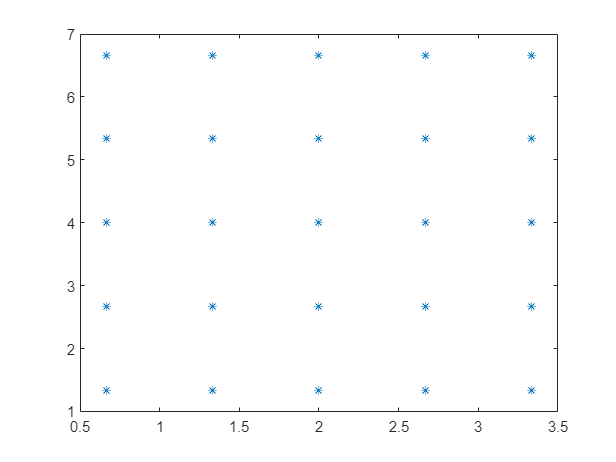

clearvars;
Nx=5;
Ny=5;
Lx=8;
Ly=8;

Vmax=0.2;
dt=10^(-4);
Ni=10^4;


N=Nx*Ny;

Posrow=Ly/(Ny+1); Poscol=Lx/(Nx+1);
i=1;
for Rows=1:Ny
 for Col=1:Nx
 x(i)=Poscol*Col/2; 
 y(i)=Posrow*Rows; 
 i=i+1;
 end
end
plot(x,y, '*')



RV=init(Lx,Ly,Nx,Ny,Vmax) 

RV =     0.6667    1.3333    0.1225   -0.0070
    1.3333    1.3333    0.1790   -0.1844
    2.0000    1.3333   -0.0101    0.0214
    2.6667    1.3333    0.0412    0.1220
    3.3333    1.3333   -0.1343   -0.0875
    0.6667    2.6667   -0.1839    0.1729
    1.3333    2.6667    0.1217    0.0930
    2.0000    2.6667   -0.1292   -0.0678
    2.6667    2.6667   -0.1243   -0.0088
    3.3333    2.6667    0.1387    0.0456


accfunc=Acc(RV,Lx,Ly,N)

accfunc = 1.0e+03 *

   -6.1681    0.0023         0
    0.0017    0.0031         0
   -0.0000    0.0032         0
   -0.0017    0.0031         0
    6.1681    0.0023         0
   -6.1676    0.0000         0
    0.0019    0.0001         0
   -0.0000    0.0001         0
   -0.0019    0.0001         0
    6.1676    0.0000         0


z1=Fx(x,y)

z1 =    -0.3706   -0.1322   -0.0294   -0.0071   -0.0020   -0.0034   -0.0035   -0.0022   -0.0011   -0.0005   -0.0002   -0.0002   -0.0002   -0.0002   -0.0001   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000


z2=Fy(x,y)

z2 =    -0.7413   -0.1322   -0.0196   -0.0035   -0.0008   -0.0135   -0.0071   -0.0029   -0.0011   -0.0004   -0.0009   -0.0007   -0.0004   -0.0002   -0.0001   -0.0001   -0.0001   -0.0001   -0.0001   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000



verletfunc=Verlet(RV,Lx,Ly,N,dt)

Index in position 2 exceeds array bounds. Index must not exceed 4.

Error in Verlet (line 9)
 x(i)=RV(i,1)+RV(i,3)*dt+RV(i,5)*(dt^2)/2; 


% mdfunc=MD(Lx,Ly,N,Ni,dt,RV)

t1=0;
t1=0.05;
t2=0.5;
t3=1.0;